Starting test 5


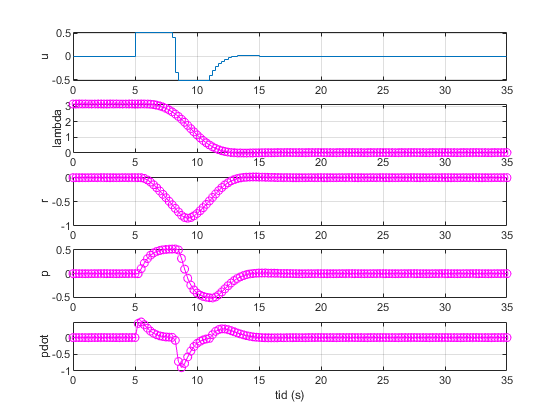

Finished test!


clear;
close all;

filename = "helicopter_dag_3";
stop_time = '25';
test_folder = 'test_plots';
name_x_k = "x_k";
name_u_k = "u_k";

start_index = 1;
should_save = false;

Q_values = [10000, 10000, 100, 100;
            1, 1, 1, 1; 
            10, 1, 1, 1;
            100, 100, 100, 100;
            10, 10, 1, 1;
            1, 1, 1, 1];
R_values = [10;
            1;
            1;
            1;
            1;
            100];

num_tests = size(R_values, 1);

indexes = start_index:num_tests + start_index - 1;
indexes = 5;  % To only run one test

load_system(filename);
set_param(filename, 'StopTime', stop_time);

for index_test = indexes
    Q = diag(Q_values(index_test, :));
    R = R_values(index_test, :);
    % Calculate optimal input
    optimal_input();
    msg = sprintf("Starting test %d", index_test);
    disp(msg);
    set_param(filename, 'SimulationCommand', 'Start');
    while true  % Waits for it to finish
        pause(1);
        status = get_param(filename, 'SimulationStatus');
        if strcmp(status, 'stopped')
            disp("Finished test!");
            break;
        end
    end
    if should_save
        test_filename_x_k = sprintf('test_plots/data_x_k_test_%d.mat', index_test);
        save(test_filename_x_k, name_x_k);
        test_filename_u_k = sprintf('test_plots/data_u_k_test_%d.mat', index_test);
        save(test_filename_u_k, name_u_k);
    end
end